# `Activity 3.1`

## `Pitch Estimation using Fourier Transform`

[y,fs] = audioread("cirk-barabannaya-drob-i-marsh_-silachi.mp3");

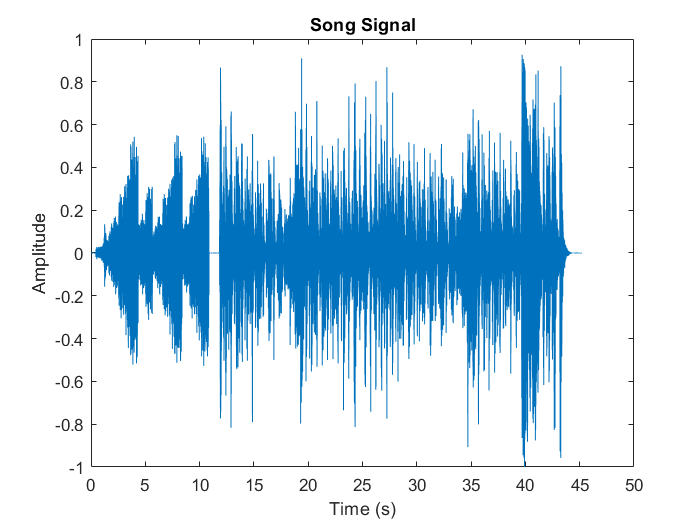

y = y(:,1); % Converts to a single channel
dt = 1/fs;
t = 0:dt:(length(y)*dt)-dt;

figure() 
plot(t,y); 
title('Song Signal'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 

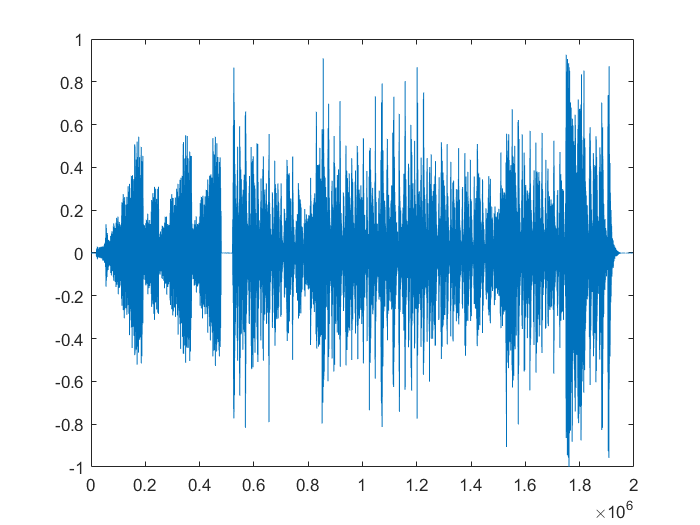

figure()
sample_array = 1:length(y);
plot(sample_array,y); 

window_size = 2 sec

window_time = 0.5;
window_samples = fs*window_time;
n_windows = floor(length(sample_array)/window_samples);

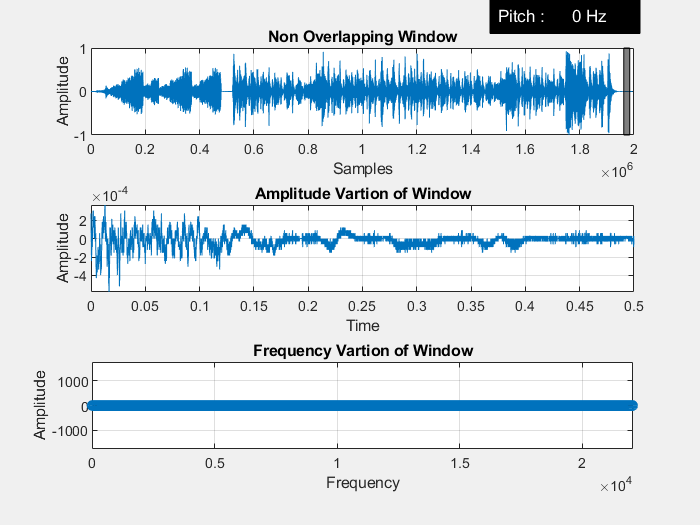

M(n_windows) = struct('cdata',[],'colormap',[]);
h = figure;
h.Visible = 'on';

aviobj = VideoWriter('myMovie_2.avi');
open(aviobj)

pitch_arr = zeros(1,n_windows);
for i=1:n_windows
    filtered_samples = (i-1)*window_samples+1 : i*window_samples+1;
    filtered_signal = y(filtered_samples);
    
    % Fourier Transform
    L = size(filtered_signal,1);
    Fn = fs/2;
    FTy = fft(filtered_signal)/L;
    Fv = linspace(0, 1, fix(L/2)+1)*Fn;
    Iv = 1:numel(Fv);
    [~,max_index] = max(abs(FTy(Iv,:))*2);
    max_frequency = Fv(max_index(1));
    pitch_arr(i) = max_frequency;
    
    %figure()
    subplot(3,1,1)
    plot(sample_array,y);

    yl = ylim;
    xl = xlim;
    xBox = [(i-1)*window_samples+1,i*window_samples+1,i*window_samples+1, (i-1)*window_samples+1];
    yBox = [yl(1),yl(1),yl(2),yl(2)];
    patch(xBox, yBox, 'black', 'FaceColor', 'black', 'FaceAlpha', 0.5);
    xlabel('Samples')
    ylabel('Amplitude')
    title("Non Overlapping Window")
    grid on
    
    subplot(3,1,2)
    t_sample = 0:dt:(length(filtered_signal)*dt)-dt;
    plot(t_sample,filtered_signal);
    xlabel('Time')
    ylabel('Amplitude')
    title("Amplitude Vartion of Window")
    grid on  
    
    subplot(3,1,3)
    stem(Fv, abs(FTy(Iv,:))*2);
    dim = [.7 .7 .3 .3];
    annotate_txt = sprintf("Pitch : %6.f Hz",max_frequency);
    t = annotation('textbox',dim,'String', ...
        annotate_txt,'FitBoxToText','on');
    
    xlabel('Frequency')
    ylabel('Amplitude')
    title("Frequency Vartion of Window")
    grid on
    
    t.Color = "white";
    t.BackgroundColor = "black";
    drawnow
    pause(0.1)
    M(i) = getframe;
    frame = getframe(gcf);
    writeVideo(aviobj,frame);  
end

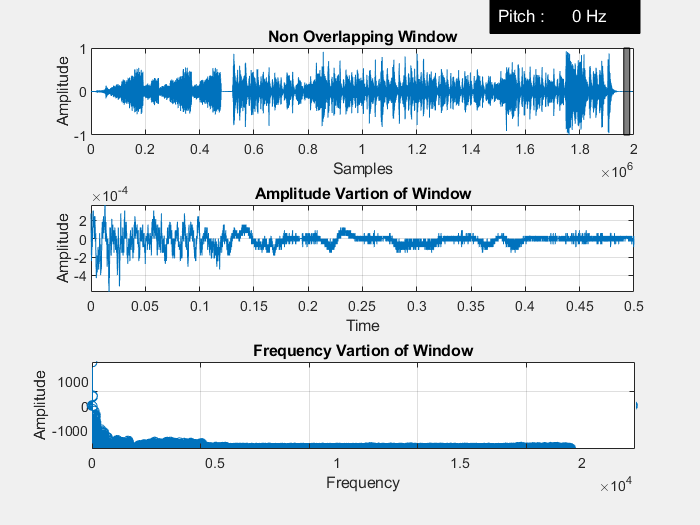

max_frequency = 281

annotate_txt = "Pitch : 281"

yl =          0    0.0180


xl =            0       25000


xBox =            0        1000        1000           0


yBox =          0         0    0.0180    0.0180


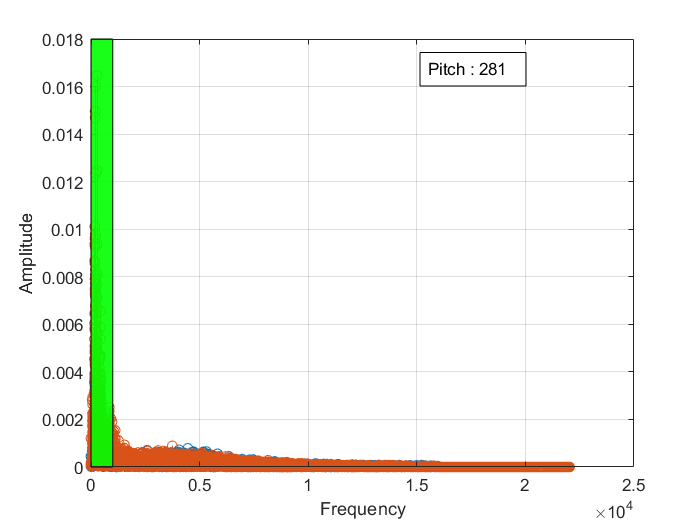

close(aviobj);